# 8.28 - Matlab Fundamentals

## Number Formats

pi

ans = 3.1416

format short; s = pi        % 5 digits

s = 3.1416

format long; l = pi         % 15 digits

l =    3.141592653589793


format short eng; s_e = pi 

s_e =      3.1416e+000


pi*1000                     % powers of 3, better sci notat

ans =      3.1416e+003


format default; d = pi

d = 3.1416

## Vectors and Arrays

B = [1 2; 6 7; 1 4]

B =      1     2
     6     7
     1     4


B_p = B'

B_p =      1     6     1
     2     7     4


C = [1 2*j; 6*i 7] 

C =    1.0000 + 0.0000i   0.0000 + 2.0000i
   0.0000 + 6.0000i   7.0000 + 0.0000i


C_p = C' % Watch the - that happens: complex conjugate

C_p =    1.0000 + 0.0000i   0.0000 - 6.0000i
   0.0000 - 2.0000i   7.0000 + 0.0000i



% Accessing individual entries
B_2 = B(2) % Goes down by column*

B_2 = 6

C_21 = C(2,1)

C_21 = 0.0000 + 6.0000i

#### Whos

% whos; % lists all the variables and size and type

## Array Creation

#### - Built-In Functions

z_23 = zeros(2,3)

z_23 =      0     0     0
     0     0     0


z_4 = zeros(4) % 4x4 matrix

z_4 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


o_24 = ones(2,4)

o_24 =      1     1     1     1
     1     1     1     1


o_3 = ones(3) % 3x3

o_3 =      1     1     1
     1     1     1
     1     1     1


% help elmat % a list of elementary matrices

#### - Colon Operator

c_163 = 1:0.6:3 % start:go_by:limit (stops b4 limit)

c_163 =     1.0000    1.6000    2.2000    2.8000


c_13 = 1:3 % assumed go_by = 1

c_13 =      1     2     3


c_52 = 5:-1.2:2 % Need a - val

c_52 =     5.0000    3.8000    2.6000


%      5:2 will not work. Need a - (assumes 1 by default)

c_col = (3:6)'  % how to create a column

c_col =      3
     4
     5
     6


        % not 3:6', won't do anything


#### - Linspace

Create a row vector w/ specific # of linearly spaced points btwn 2 #s

ls_016 = linspace(0,1,6) % start, end, n

ls_016 =          0    0.2000    0.4000    0.6000    0.8000    1.0000


ls_01 = linspace(0,1) % 100 points default

ls_01 =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


ls_t016 = ls_016' % transpose

ls_t016 =          0
    0.2000
    0.4000
    0.6000
    0.8000
    1.0000


#### - Logspace

Create row vector w/ logarithmically spaced points btwn 2 #s

lgs_124 = logspace(-1,2,4) % 10^-1 -> 10^2 w/ n = 4

lgs_124 =     0.1000    1.0000   10.0000  100.0000


lgs_12 = logspace(-1,4) % 100 default? or 50?

lgs_12 = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0014    0.0018    0.0022    0.0028    0.0036    0.0045    0.0057    0.0072    0.0091    0.0115    0.0146    0.0184    0.0233    0.0295    0.0373    0.0471    0.0596    0.0754    0.0954    0.1207    0.1526    0.1931    0.2442    0.3089    0.3907    0.4942    0.6251    0.7906    1.0000


% transpose to make vertical

## Character Strings and Ellipsis

% alphanumeric constants: use ''
a_1 = 'Miles ';
a_2 = 'Davis'

a_2 = 'Davis'

a_concat = [a_1 a_2] % paste two strings together

a_concat = 'Miles Davis'


% ellipsis - use to continue long lines, save space
a_el = [1 2 3 4 5 ...
    6 7 8]

a_el =      1     2     3     4     5     6     7     8


quote = ['Any fool can make a rule,' ...
    ' and any fool will mind it.']

quote = 'Any fool can make a rule, and any fool will mind it.'

#### - Useful Character Functions

num_char = length(a_1) 

num_char = 6

same_str_yn = strcmp(a_1, a_2) % are 2 strings exactly equal?

same_str_yn = logical
   0



s_5 = '5'

s_5 = '5'

n_s5 = str2num(s_5)

n_s5 = 5

s_ns5 = num2str(n_s5)

s_ns5 = '5'


rep_str = strrep(a_concat, 'iles', 'y little')

rep_str = 'My little Davis'

i_str = strfind(rep_str, 'little') % looks for 'little' 

i_str = 4

                                   % in rep_str, returns
                                   % 1st index of it
i_str_no = strfind(rep_str, 'Little') % no results


i_str_no =

     []



a_1_up = upper(a_1)

a_1_up = 'MILES '

a_1_lo = lower(a_1)

a_1_lo = 'miles '

## Complex Numbers

% these are equivalent
x = 2+i*4

x = 2.0000 + 4.0000i

x_1 = 2+4i

x_1 = 2.0000 + 4.0000i

x_2 = 2+4j

x_2 = 2.0000 + 4.0000i

## Vector-Matrix Calcs

D = [1 2; 3 4; 5 6];
E = [1 2 3; 4 5 6];
DE_mat = D*E % D_c = E_r -> matrix multiplication

DE_mat =      9    12    15
    19    26    33
    29    40    51


% .* -> element wise, need same size matrix
% A^2 (need square)

## Built-In Functions

% help elfun % trig/exp/complex/rounding ftns list
% lookfor ceil

## Graphics

t = [0:2:20]';
g = 9.81; m = 68.1; c_d = 0.25;
v = sqrt(g*m/c_d) * tanh(sqrt(g*c_d/m)*t);
plot(t, v, 'ro:')
% ro: -> red dotted lines, circles @ points
% gd -> green diamonds, no line
% m-- -> magenta dashed line with no point symbols
title('Plot of v versus t');
xlabel('Values of t')
ylabel('Values of v');
grid;
hold off;

#### - Subplot

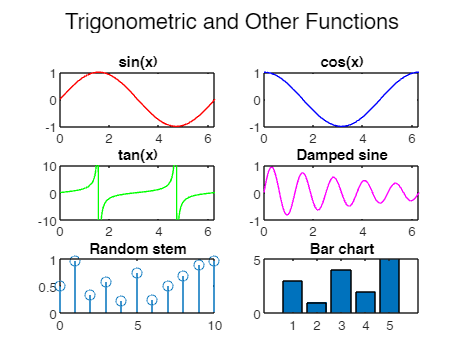

x = linspace(0,2*pi,200);

% First subplot
subplot(3,2,1); % 3 rows, 2 cols, position 1
plot(x, sin(x), 'r');
title('sin(x)');

% Second subplot
subplot(3,2,2);
plot(x, cos(x), 'b');
title('cos(x)');

% Third subplot
subplot(3,2,3);
plot(x, tan(x), 'g');
ylim([-10 10]); % limit y for better view
title('tan(x)');

% Fourth subplot
subplot(3,2,4);
plot(x, exp(-0.2*x).*sin(5*x), 'm');
title('Damped sine');

% Fifth subplot
subplot(3,2,5);
stem(0:10, rand(1,11));
title('Random stem');

% Sixth subplot
subplot(3,2,6);
bar(1:5, [3 1 4 2 5]);
title('Bar chart');

sgtitle('Trigonometric and Other Functions');